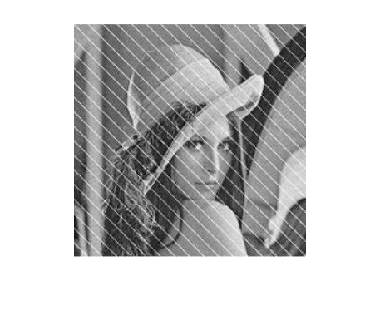

% Load Image
I = truecolorload('./images/4lena.png');
I = I(:,:,1);
imshow(I);

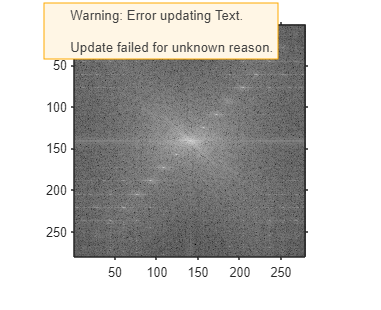


% Get FFT
[F, s] = spatial2freq(I);
F = fftshift(F);
imshow(s, []); axis on;

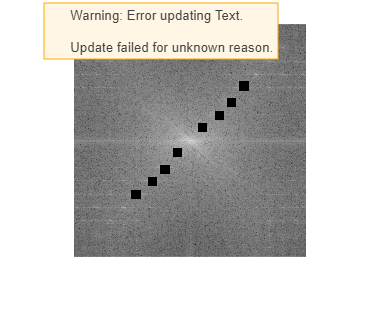


% Apply notch filters
% lena flipped
% filters = [
%   197 325 207 335
%   178 304 188 314
%   197 070 207 080
%   178 050 188 060
%   048 177 058 187
%   070 197 080 207
%   304 177 314 187
%   325 197 335 207
%   178 177 188 187
%   197 197 207 207
% ];
% filters = [
%    155 130 165 140
%    090 130 100 140
%    025 130 035 140
%    355 130 365 140
%    415 130 425 140
%    485 130 495 140
%    155 385 165 395
%    090 385 100 395
%    025 385 035 395
%    355 385 365 395
%    415 385 425 395
%    485 385 495 395
%    155 065 165 075
%    090 065 100 075
%    025 065 035 075
%    355 065 365 075
%    415 065 425 075
%    485 065 495 075
%    155 455 165 465
%    090 455 100 465
%    025 455 035 465
%    355 455 365 465
%    415 455 425 465
%    485 455 495 465
%    315 255 325 265
%    370 255 380 265
%    140 255 150 265
%    200 255 210 265
% ];
filters = [
    120 150 130 160
    150 120 160 130
    105 170 115 180
    170 105 180 115
    090 185 100 195
    185 090 195 100
    070 200 080 210
    200 070 210 080
];
filter_count = size(filters, 1);
for i = 1:filter_count
    x1 = filters(i, 1);
    y1 = filters(i, 2);
    x2 = filters(i, 3);
    y2 = filters(i, 4);
    dx = x2 - x1;
    dy = y2 - y1;
    F(x1:x2, y1:y2) = 0;
end

% Display result
s = abs(F);
s = log(s + 1);
imshow(s, []);

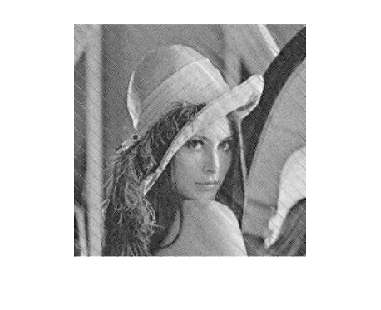


% Freq => spatial
O = freq2spatial(ifftshift(F));
imshow(O, [0 255]);